# Source parameter matrix inversion

* Make sure that you are in the correct directory otherwise the catalog that will be loaded will be loaded might be wrong

## Build up the matrix

load analysis_catalog.mat
% Basic variables
% All variables are presented in SI units if not otherwise indicated

M                   = CAT.MSmag;
Mo                  = 10.^((M+10.7)*3/2)/10^7;
depth               = CAT.MSdepth*1000;
productivity        = CAT.MSprod;
residualProductivity= CAT.MSres;
MeBB                = CAT.MeBB_appended_cat1;
MeHF                = CAT.MeHF_appended_cat1;
meanSlip            = CAT.av_slip_appended_cat2;
faultWidth          = CAT.rwid_appended_cat2*1000;
faultLength         = CAT.rlen_appended_cat2*1000;
faultPerimeter      = CAT.Perimeter_appended_cat2;
stressDrop          = CAT.StressDrop_appended_cat2*10^6;
heterogeneity       = CAT.EllipseErrorNorm_appended_cat2;

% normalized/linearized parameters:

logSD               = log10(stressDrop);
MeBBNorm            = MeBB./M;
MeHFNorm            = MeHF./M;
depthNorm           = abs(depth-mean(depth))/mean(depth);
Ar                  = faultWidth./faultLength;
Ar(Ar<1)            = 1./Ar(Ar<1);
logAr               = Ar;
PNorm               = faultPerimeter./(2*pi*(Mo*7/16./stressDrop).^(1/3));
H                   = heterogeneity;

% store variables into X
X = [logSD, MeBBNorm, MeHFNorm, depthNorm, logAr, PNorm, H];
Y = residualProductivity;
badI = any([isnan(X),isinf(X),isnan(Y),isinf(Y)],2);
X = X(~badI,:);
Y = Y(~badI);
SX= size(X);
X = X - repmat(mean(X,1),SX(1),1); % remove average value
Y = Y - mean(Y);


## Inervert matrix for set of parameters

BETA = (X'*X)\X'*Y;
% comput2 R^2
R2         = 1  -  sum((X*BETA - Y).^2)/sum(Y.^2)

R2 = 0.1864

R2adjusted = 1  -  (SX(1)-1)/(SX(1)-SX(2)) * sum((X*BETA - Y).^2)/sum(Y.^2)

R2adjusted = 0.1050

## Remove ouliers and repeat

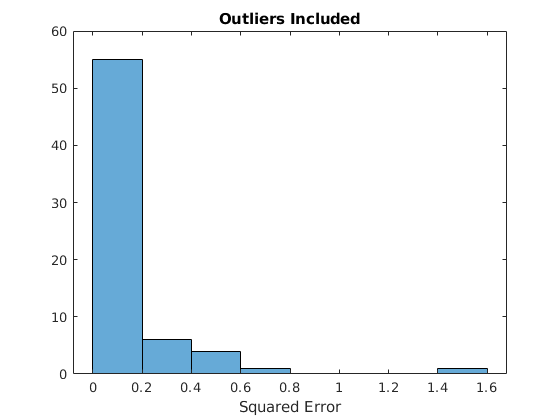

% remove outlier (rinse and repeat)

figure
var = (X*BETA - Y).^2;
histogram(var)
xlabel('Squared Error')

title('Outliers Included')


outlierInd = var > 4*mean(var);
X = X(~outlierInd,:);
Y = Y(~outlierInd);
SX= size(X);
X = X - repmat(mean(X,1),SX(1),1); % remove average value
Y = Y - mean(Y);
BETA = (X'*X)\X'*Y;

% comput2 R^2
R2         = 1  -  sum((X*BETA - Y).^2)/sum(Y.^2)

R2 = 0.2109

R2adjusted = 1  -  (SX(1)-1)/(SX(1)-SX(2)) * sum((X*BETA - Y).^2)/sum(Y.^2)

R2adjusted = 0.1278

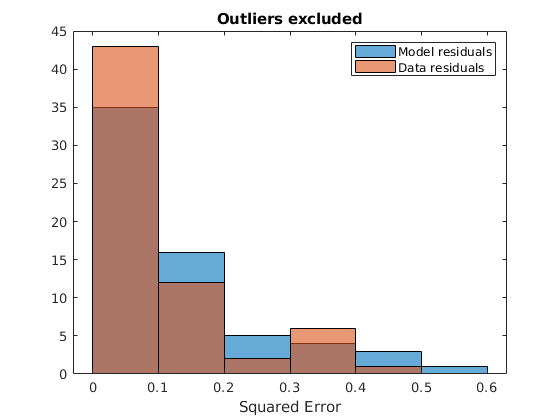


figure
histogram(Y.^2)
hold on
histogram((X*BETA - Y).^2);
xlabel('Squared Error')

legend({'Model residuals','Data residuals'})
title('Outliers excluded')

##  random sample

Xrand     = rand(SX(1),SX(2));
Yscaled   = Y./max(Y);
BETA = (Xrand'*Xrand)\Xrand'*Yscaled;
R2         = 1  -  sum((Xrand*BETA - Yscaled).^2)/sum(Yscaled.^2)

R2 = 0.0736

R2adjusted = 1  -  (SX(1)-1)/(SX(1)-SX(2)) * sum((Xrand*BETA - Yscaled).^2)/sum(Yscaled.^2)

R2adjusted = -0.0239

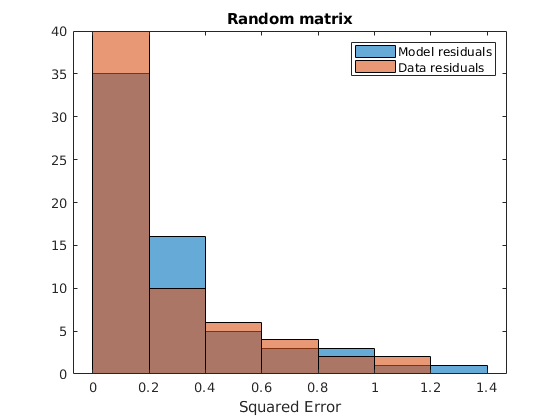


figure
histogram(Yscaled.^2)
hold on
histogram((Xrand*BETA - Yscaled).^2);
xlabel('Squared Error')

legend({'Model residuals','Data residuals'})
title('Random matrix')

**Best subset of parameters**

R       = zeros(1,SX(2));
Rrand   = R;

for n = 1:SX(2)
    Xcol    = X(:,n);
    BETA    = (Xcol'*Xcol)\Xcol'*Y;
    R(n)    = 1  -  sum((Xcol*BETA - Y).^2)/sum(Y.^2);  
end
maxR = max(R)

maxR = 0.1794


mIt = 10000;
maxRandom = zeros(mIt,1);
for m = 1:mIt
    for n = 1:SX(2)
        Xrand   = rand(SX(1),1);
        BETArand= (Xrand'*Xrand)\Xrand'*Yscaled;
        Rrand(n)= 1  -  sum((Xrand*BETArand - Yscaled).^2)/sum(Yscaled.^2);
    end
    maxRandom(m) = max(Rrand);
end

SourceParameters = {'logSD', 'MeBBNorm', 'MeHFNorm', 'depthNorm', 'logAr', 'PNorm', 'H'};
Rvalues = table(SourceParameters',R')

Rvalues = 7×2 table
       Var1           Var2   
    ___________    __________

    'logSD'         0.0033013
    'MeBBNorm'      0.0077981
    'MeHFNorm'       0.022488
    'depthNorm'    0.00033756
    'logAr'           0.17943
    'PNorm'        2.2488e-05
    'H'              0.058144


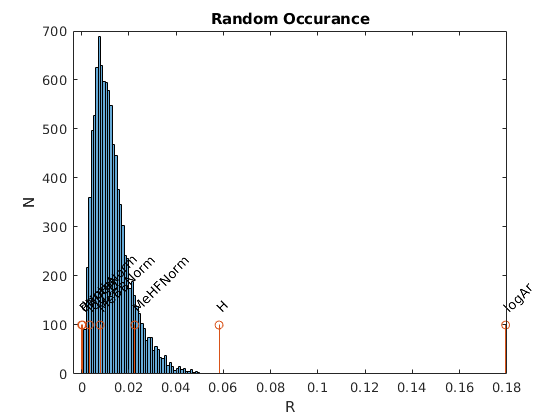


figure 
histogram(maxRandom)
hold on
stem(R,sqrt(mIt)*ones(length(R), 1))
texth = text(R, 1.3*sqrt(mIt)*ones(length(R),1), SourceParameters);
set(texth, 'Rotation', 45)
xlabel('R')
ylabel('N')
title('Random Occurance')

## Afterthought: Focal mechanism

From the above analysis it appears that, generally, source parameters provide little predictive value for the productivity of the aftershock sequence. Possible exceptions are the aspect ratio of ruptures and, even, more subtle, the heterogeneity of the rupture. We can test wether these factors, (high aspect ratios and relatively high aspect ratios), which are charateristic of strike slip earthquakes are the cause of their relative depletion in aftershocks. To do this, I consider the average value of these paramters for strike slip earthquakes and predict the residual productivity based on the inversion. 

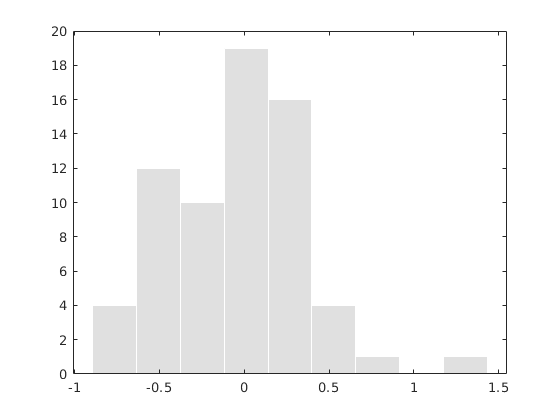

colChoice = [5,7];
figure
resRange    = minmax(residualProductivity(~isnan(residualProductivity') & ~isinf(residualProductivity'))');
binEdges    = linspace(resRange(1),resRange(2),10);
histogram(residualProductivity,binEdges,'FaceColor', [0.8 0.8 0.8],'EdgeColor',[1 1 1])

fms         = fms(~badI);

Undefined function or variable 'fms'.

fms         = fms(~outlierInd);

hold on
C = {'b','g','r'};
Xfms = zeros(3,length(colChoice));
for n =1:3
    I = fms == n;
    histogram(residualProductivity(I),binEdges,'FaceColor',C{n},'EdgeColor',[1 1 1])
    Xfms(n,:) = mean(X(I,colChoice),1);
end
% inverse problem
Xgood = X(:,colChoice);
BETAgood = (Xgood'*Xgood)\Xgood'*Y;
% forward prediction:
Yprediction = Xfms*BETAgood;
for n = 1:3
    stemH1 = stem(Yprediction(n),15,C{n},'filled');
    stemH2 = stem(mean(Y(fms == n)), 15, C{n});
end
legend({'All data','SS','Normal','Reverse', ...
    'SS Prediction','SS Observed', ...
    'Normal Prediction','Normal Observed', ...
    'Reverse Prediction', 'Reverse Observed'})

figure
resRange    = minmax(Y');
binEdges    = linspace(resRange(1),resRange(2),10);
histogram(Y,binEdges,'FaceColor', [0.8 0.8 0.8],'EdgeColor',[1 1 1])
hold on
YpredAll = Xgood*BETAgood;
pctRange = prctile(YpredAll,[0,20,80,100]);
for n = 1:3
    Ipct = YpredAll >= pctRange(n) & YpredAll < pctRange(n+1);
    histogram(Y(Ipct), binEdges, 'FaceColor',C{n},'EdgeColor',[1 1 1])
    stem(mean(Y(Ipct)), 10,C{n});
end
for n = 1:3
    stem(mean(Y(fms == n)), 10, C{n},'filled')
end
legend({'All data','Low','','Average','','High','','SS','Normal','Reverse'})
title('Forward prediction of productivity')

As a seprate test we can also see whether these parameters are also good at seperating the data in the population of another focal mechanism.

figure
histogram(residualProductivity,binEdges,'FaceColor', [0.8 0.8 0.8],'EdgeColor',[1 1 1])
hold on
I = fms == 3 ;
for n = 1:3
    Ipct = YpredAll >= pctRange(n) & ...
        YpredAll < pctRange(n+1) & ...
        I;
    
    histogram(Y(Ipct), binEdges, 'FaceColor',C{n},'EdgeColor',[1 1 1])
    stem(mean(Y(Ipct)), 10,C{n});
    stem(mean(YpredAll(Ipct)),C{n},'filled')
end
legend({'All data','Low','','Average','','High',''})


The above formalism provide an objective basis  to understand why strike slip earthquakes may be deficient in aftershocks.